# Archivo Principal. Modelo MAS y mecanismo para gestión de demanda.


% Test for mechanism with social incentives (opinion dynamics), with Bullo stubbornnes model. 
% Replicator dynamics used for resource allocation optimization.

clear

clc

close all

global G beta_ef N T_ hybrid b op devices

devices = xls2struct('devices.xlsx'); %cargar los aparatos que tienen las casas de cada usuario.
%load('Prefs.mat');
%number of populations (consumers, households)
P = 6;
% number of agents per population (devices)
N = length(devices.id);

%step_1_graph % graph network generation, for the user's opinions interaction

%step_2_opdyn % opinion dynamics

## Users preferences

No genera gráfica
Fin perfil Nevera 3
No genera gráfica
Fin perfil Luminaria2OC
No genera gráfica
Fin perfil Luminaria2OC
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Ducha
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Plancha
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Cargador Pc Portatil
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Horno Microondas
No genera gráfica
Fin perfil Licuadora
No genera g

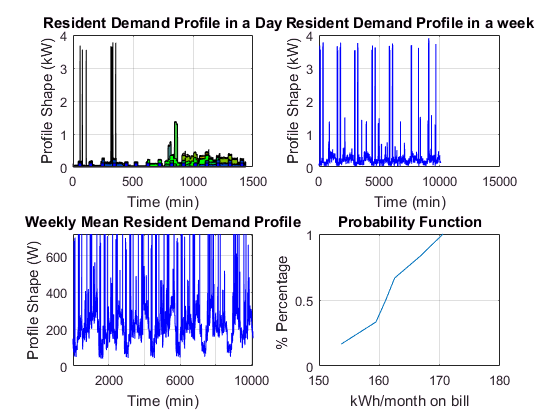

T_ = 14;%10080/5; %weekly period with hourly resolution.
Tperf = 10080;
 PrefsOrig = zeros(N,Tperf,P);%randi([0 1], N,T_,P);
 Perfiles = Perfcas2(P,1);

 
 kWhOrig = sum(Perfiles.Total)/60;

for i=1:length(devices.id)
    %update default power definition for each device with data in the
    %profiles
    devices.power(i) = ceil(max(max(Perfiles.(devices.id{i}))));
    
    %copy Perfiles to variable Prefs, changing organisation
    
    for u = 1:P
        PrefsOrig(i,:,u) = Perfiles.(devices.id{i})(:,u);
    end
    
end

%Undersampling of the profiles, to match game runtime periods.
factor = Tperf/T_;
Prefs = pUndersample(PrefsOrig, factor);
%save('Prefs','Prefs','PrefsOrig','Perfiles','devices');

%length(nonzeros(PrefsOrig(1,:,1)))
%length(nonzeros(Prefs(1,:,1)))*factor

PowOpt = zeros(P,T_);
for u = 1:P
    PowOpt(u,:)=squeeze(sum(power_state(Prefs(:,:,u)+1)));
end
PowOptTotal = sum(PowOpt)/1000';


## Periods for applying incentives

Iperiods = PowOptTotal > mean(PowOptTotal);

Iper(Iperiods);

## Stuff

% parametros de la func. de costo agregado
%beta_ef = 450; 
b = 0;

% number of pure strategies per population
n = 2; %T_+1;%(24*7)+1;%25

## discrete

Running the pairwise_comparison revision protocol, period T=1
Elapsed time is 0.309426 seconds.
 


Running the pairwise_comparison revision protocol, period T=2
Elapsed time is 0.313889 seconds.
 


Running the pairwise_comparison revision protocol, period T=3
Elapsed time is 0.305365 seconds.
 


Running the pairwise_comparison revision protocol, period T=4
Elapsed time is 0.311066 seconds.
 


Running the pairwise_comparison revision protocol, period T=5
Elapsed time is 0.312899 seconds.
 


Running the pairwise_comparison revision protocol, period T=6
Elapsed time is 0.305595 seconds.
 


Running the pairwise_comparison revision protocol, period T=7
Elapsed time is 0.311154 seconds.
 


Running the pairwise_comparison revision protocol, period T=8
Elapsed time is 0.322462 seconds.
 


Running the pairwise_comparison revision protocol, period T=9
Elapsed time is 0.322477 seconds.
 


Running the pairwise_comparison revision protocol, period T=10
Elapsed time is 0.309427 seconds.
 


Running the pairwise_comparison revision protocol, period T=11
Elapsed time is 0.307177 seconds.
 


Running the pairwise_comparison revision protocol, period T=12
Elapsed time is 0.308128 seconds.
 


Running the pairwise_comparison revision protocol, period T=13
Elapsed time is 0.306905 seconds.
 


Running the pairwise_comparison revision protocol, period T=14
Elapsed time is 0.304500 seconds.
 


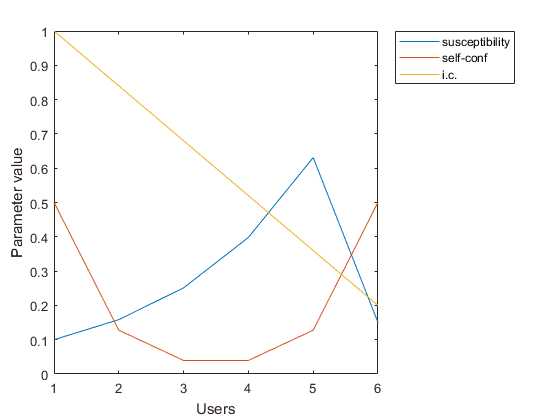

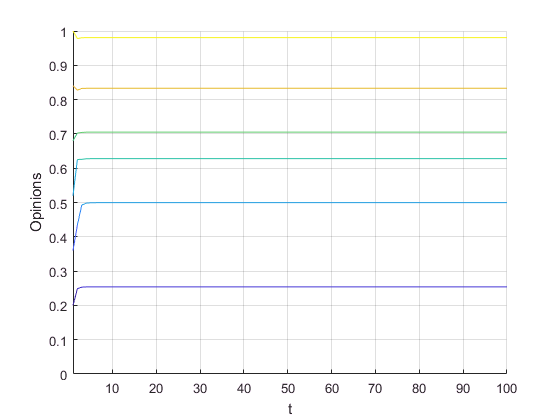

% mass of the population
%m = 1;

% initial condition
x0 = 0; %[0.2 0.7 0.1]; 

% simulation parameters
iterations = 100;

% structure with the parameters of the game
G = struct('P', P, 'N', N, 'n', n, 'pop_wise', 0, 'f', @fitness_user_finite, 'time', iterations, 'eta', 0.02, 'revision_protocol', @pairwise_comparison);

G.R = 1;% There are as many revisions per iteration as agents are in a population.


% verify data of the game
G = definition(G);

G.T_ = T_; %assign run periods to the ciclic game.
G.Prefs = Prefs; %users' preferences for each period.

Qp = zeros(T_,G.P);
Incentives = zeros(G.T_,G.time,G.N,G.P);

tdyn = tic;
for run = 1:G.T_
G.period = run; %present period
G.run_finite();
Incentives(run,:,:,:) = reshape(G.Inc,[G.time,G.N,G.P]);
Qperiod = reshape(G.Q(end,:),G.N,G.P);
Qp(run,:) = sum(Qperiod)/1000;
end


totaldyn = toc(tdyn);
disp(['Total elapsed time running pop dynamics: ',num2str(totaldyn),' s'])

Total elapsed time running pop dynamics: 4.7093 s


disp(' ')

%G.graph()
%G.graph_evolution()
%G.graph_fitness()

## continues standard

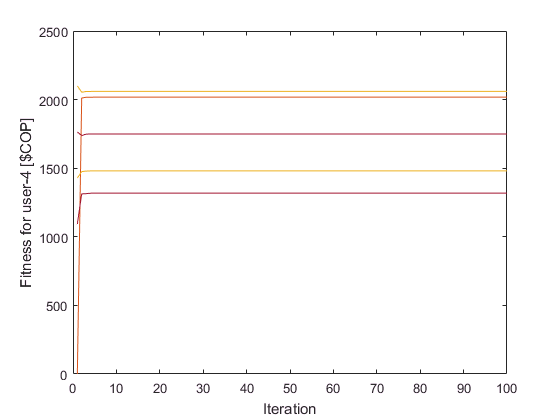

Q_e = reshape(G.Q(end,:), [G.N,G.P]);
Q_s = reshape(G.Q(1,:), [G.N,G.P]);

user = 4;
FitEvo = zeros(G.time,G.N);
for t = 1:G.time
FitEvo(t,1:G.N) = G.F(t,user*(1:G.N));
end

figure(10)
tfit = 1:G.time;
plot(tfit,FitEvo)
xlabel('Iteration');
yinfo = strcat('Fitness for user','-',num2str(user),' [$COP]');
ylabel(yinfo)



% extract matrix of strategies. 
%MC. A strategy to make a consumption in a specific time t.
%x_n = vec2mat(G.X(end, :), n);

## Calculos de potencia por periodo

timem = 1:T_;
Qpt = sum(Qp,2);

disp('Coincide la potencia del caso natural(prefs) con la consumida:')

Coincide la potencia del caso natural(prefs) con la consumida:


size(nonzeros(eq(PowOptTotal'*1000, round(Qpt*1000))))

ans =      7     1


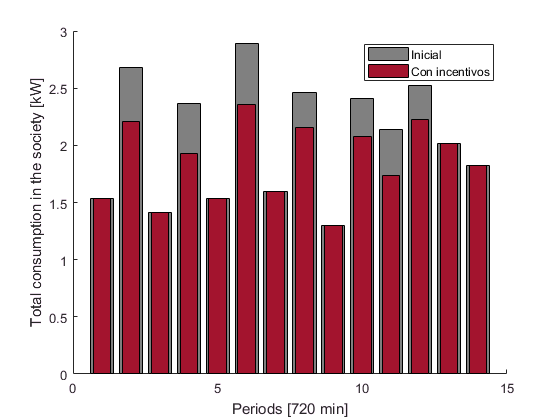



labelperiods  = periodClass(T_);

figure(1);
hold on;
bar(timem,PowOptTotal,0.8,'FaceColor',[.5 .5 .5]);
bar(timem,Qpt,0.6,'FaceColor',[.64 .08 .18]);

legend('Inicial','Con incentivos')
xlabel(labelperiods);
ylabel('Total consumption in the society [kW]')
%axis([1 T_ (min(Qpt)-0.1) (max(Qpt)+0.1)])
%hold on
%bar(timem,Qpt*0.5)
hold off



kWhSemTotal = sum(Qpt)/(60/factor)

kWhSemTotal = 310.8720


kWh_User = sum(Qp)/(60/factor)

kWh_User =    62.0160   58.5600   55.7760   60.3840   53.5440   20.5920



%figure(2)

## Otras graficas

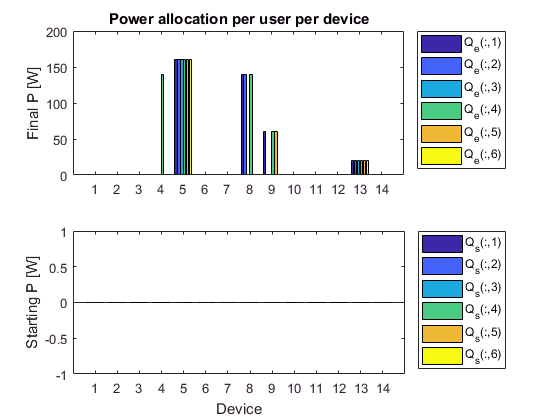

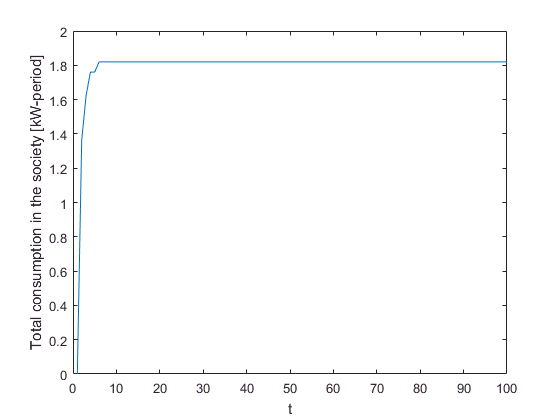

figure(4); 
clf



subplot(2,1,1), bar(Q_e,'DisplayName','Q_e')
titPower = strcat('Final P [W]');%, % addcost: ', num2str(addcost));
%title(titPower)
%xlabel('Device') % x-axis label
ylabel(titPower) % y-axis label
legend('show', 'Location','northeastoutside')

title('Power allocation per user per device')
%figure(5); 
%clf
subplot(2,1,2), bar(Q_s,'DisplayName','Q_s')
titPower = strcat('Starting P [W]');%, % addcost: ', num2str(addcost));
%title(titPower)
xlabel('Device') % x-axis label
ylabel(titPower) % y-axis label
legend('show', 'Location','northeastoutside')






%nameP = strcat('power',netType,num2str(P),social_incentives);
%savefig(4, nameP, 'compact');


%disp(['Energy use ratio: ' num2str(total_resources_alloc/sum(m))]);
timeQ = 1:size(G.Q,1);
Qavg = zeros(1,size(G.Q,1));
for i= timeQ
     Qavg(i) = sum(G.Q(i,:))/1000;
end

figure(6)
plot(timeQ,Qavg)
xlabel('t');
ylabel('Total consumption in the society [kW-period]')